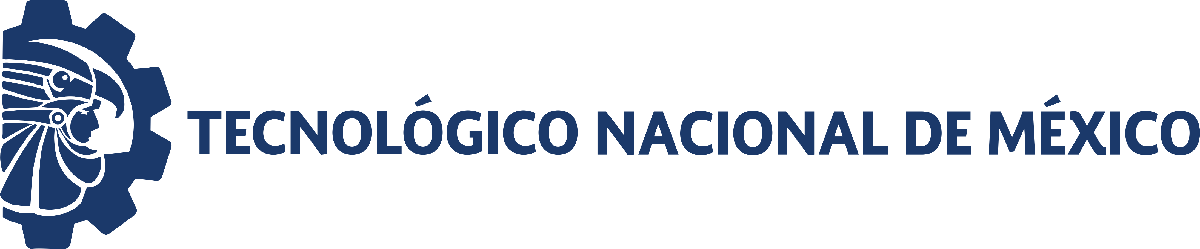                                 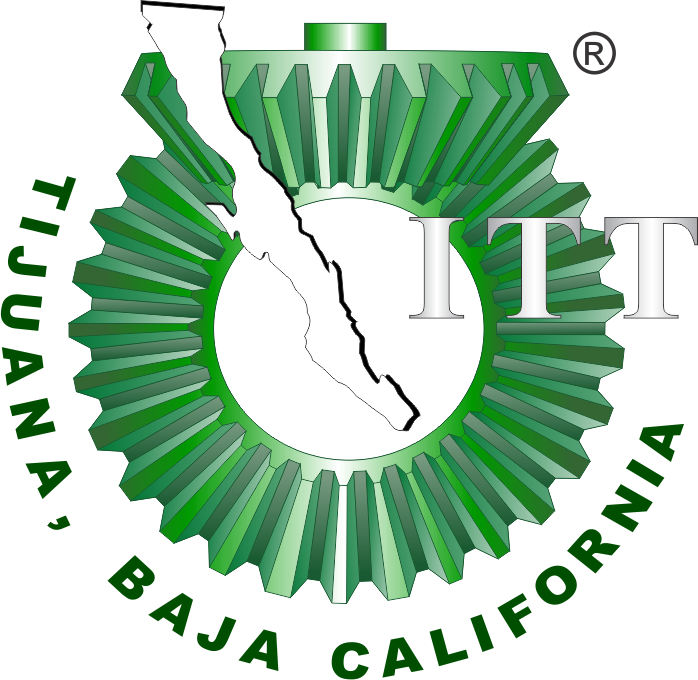

# Práctica 4: Sistema cardiovascular.

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

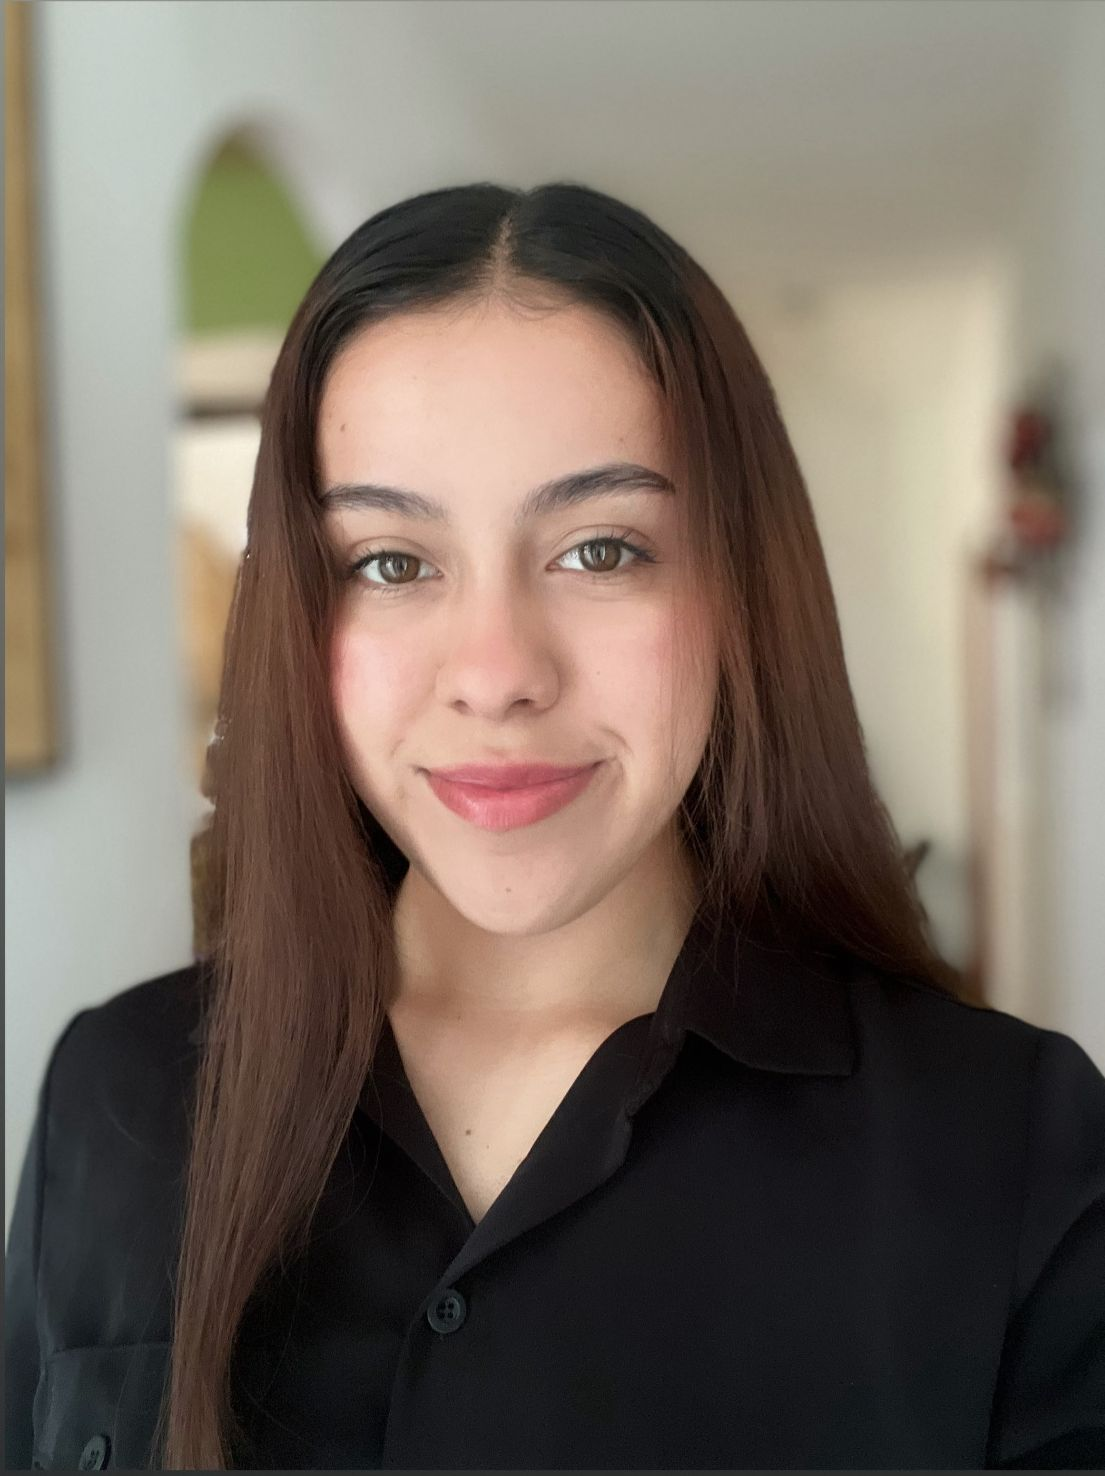

Nombre del alumno: Puentes Hernandez Yoseline Lizeth

Número de control: 22212265

Correo institucional: l22212265**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='10';
file='Sistema3';
open_system(file);
parameters.StopTime=tend;
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
set_param('Sistema3/Ppa(t)','Minimum','-0.2');
set_param('Sistema3/Ppa(t)','Maximum','1');
set_param('Sistema3/Ppa(t)','Seed','106');
set_param('Sistema3/Ppa(t)','SampleTime','0.5');



## Respuesta lazo abierto

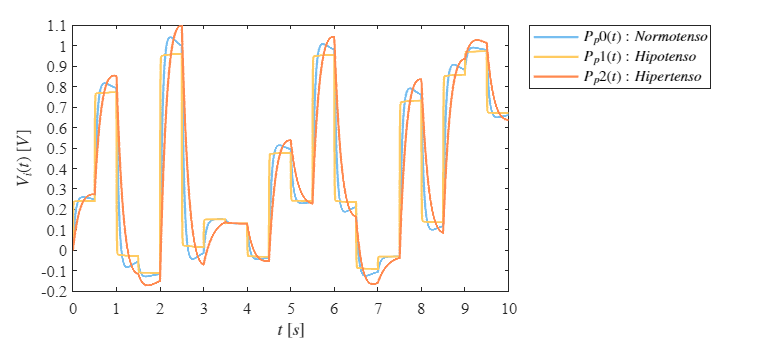

Signal='Lazo abierto';
x1=sim(file,parameters);
writematrix(x1.Ppa,'Signal.xlsx')
plotsignals(x1.t,x1.Pp0,x1.Pp1,x1.Pp2,Signal)

## Respuesta lazo cerrado

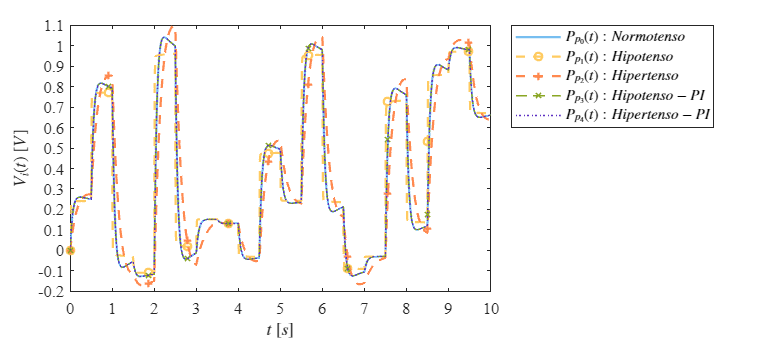

Signal='Lazo cerrado';

x2=sim(file,parameters);
plotsignal(x2.t,x2.Pp0,x2.Pp1,x2.Pp2,x2.Pp3,x2.Pp4, Signal)

## Funcion: Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Signal)
       set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

mycolors = [119,190,240;
            255,203,97;
            255,137,79;
            138,166,036;
            092,047,194;
            234,91,111]/255;
colororder(mycolors)

 plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));

  L= legend('$P_p0(t):Normotenso$','$P_p1(t):Hipotenso$','$P_p2(t):Hipertenso$');
  set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');


xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$V_i(t)$ $[V]$','Interpreter','Latex', 'FontSize',11)

xlim([0,10]); xticks (0:1:10)
if Signal=="Lazo abierto"
    ylim([-0.2,1.1]);yticks(-0.2:0.1:1.1)
end

exportgraphics(gcf,[Signal,'Cardiovascular.pdf'],'ContentType','Vector')
exportgraphics(gcf,[Signal,'Cardiovascular.png'],'ContentType','Vector')

end

function plotsignal(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;

mycolors = [119,190,240;
            255,203,97;
            255,137,79;
            138,166,036;
            092,047,194;
            234,91,111]/255;
colororder(mycolors)

  p=plot(t, Pp0, '-', t, Pp1,'--o', t, Pp2,'--+', t, Pp3,'--x', t, Pp4,':',...
    'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
  set(p(4),'LineWidth',1);set(p(5),'LineWidth',1);
  L= legend('$P_{p_0}(t):Normotenso$','$P_{p_1}(t):Hipotenso$','$P_{p_2}(t):Hipertenso$','$P_{p_3}(t):Hipotenso-PI$','$P_{p_4}(t):Hipertenso-PI$');
  set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');


xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$V_i(t)$ $[V]$','Interpreter','Latex', 'FontSize',11)

xlim([0,10]); xticks (0:1:10)
if Signal=="Lazo cerrado"
    ylim([-0.2,1.1]);yticks(-0.2:0.1:1.1)
end

exportgraphics(gcf,[Signal,'Cardiovascular.pdf'],'ContentType','Vector')
exportgraphics(gcf,[Signal,'Cardiovascular.png'],'ContentType','Vector')

end
